%This is the main body of this computer assignment
clc
clear all

## Creating the raised-cosine pulse

%We simply generate the raised-cosine with the given values
Beta = 0; 
T = 1;
Fs = 10;
L = T*Fs;
[~, Raised_Cosine] = Raised_Cosine_Pulse(T, Fs, Beta);

## Modulated Symbol and Transmission signal generation

%Here we proceed to create the modulated symbols.

N = 1e6;
%Here we create the random bits
bits = rand(1, N);
modulated_symbols = zeros(1,length(bits));
%In the following loop we assign the values -3 -1 1 3 to each symbol
%Based on the interval where each bit is located.
for i=1:length(bits)
    %Symbol A
     if (bits(i)<0.1 && bits(i)>=0)
        modulated_symbols(i) = -3;
     end
     %Symbol B
     if (bits(i)>=0.1 && bits(i)<0.5)
        modulated_symbols(i) = -1;
     end
    %Symbol C
     if (bits(i)>=0.5 && bits(i)<0.9)
        modulated_symbols(i) = 1;
     end
    %Symbol D
     if (bits(i) >= 0.9 && bits(i) < 1)
        modulated_symbols(i) = 3;
     end
end
%Now we proceed to create the transmission signal
temp = upsample(modulated_symbols, L);
temp = temp(1 : (end -(L - 1)));
%Now we create the transmitted signals with the help of convolution.
transmitted_signal = conv(temp, Raised_Cosine);

## Received Signal vector generation

%Here we shall model the AWGN channel and create noise for it.
%First we define some needed stuff as commanded in the assignment
%description.
SNR_dB = 0:10;
SNR = (10).^(SNR_dB./10) ;
ETA = var(transmitted_signal)./SNR;
%Here we create the noise, we must pay attention that it doesn't matter
%which transmitted signal length we choose for they are all the same.
Noise = randn(1,length(transmitted_signal));
Noise = diag(sqrt(ETA./2))*repmat(Noise,11,1);
%Here we define the received signal
received_signal = repmat(transmitted_signal,11,1)+ Noise;

## Symbol Detection with Maximum likelihood and error probability calculation

%Here we shall attempt to detect the symbols.

%With the help of the hint in the assignment description we have(L=T*Fs)
T_sampling = 6*L + 1 : L : (N+6-1)*(L) + 1;
%Now we create the samples.
samples = received_signal(:,T_sampling);
%Now we detect the symbols
detected_symbols_Maximum_Likelihood = zeros(size(samples));
%It is obvious that the values inside the ifs are the coresponding Deltas
%obtained with written Analysis.
for i = 1 : length(SNR_dB)
    for j = 1 : length(samples)
        if (samples(i,j) <= -2)
            detected_symbols_Maximum_Likelihood(i,j) = -3;
        end
        if (samples(i,j) > -2 && samples(i,j) <= 0)
            detected_symbols_Maximum_Likelihood(i,j) = -1;
        end
        if (samples(i,j) > 0 && samples(i,j) <= 2)
            detected_symbols_Maximum_Likelihood(i,j) = 1;
        end
        if (samples(i,j) > 2)
            detected_symbols_Maximum_Likelihood(i,j) = 3;
        end
    end
end

Maximum_Likelihood_Error = zeros(1,length(SNR_dB));
for i = 1 : length(SNR_dB)
    for j = 1:length(detected_symbols_Maximum_Likelihood)
        if detected_symbols_Maximum_Likelihood(i,j) ~= modulated_symbols(j)
            Maximum_Likelihood_Error(i)=Maximum_Likelihood_Error(i)+1;
        end
    end
end
PE_ML = reshape(Maximum_Likelihood_Error, [1 11])/N;

## Symbol Detection with Maximum a posteriori and error probability calculation

%Here we shall calcualte the error probability and plot the required
%graphs.
%It is obvious that the values inside the ifs are the coresponding Deltas
%obtained with written Analysis.

Delta1= -0.5*ETA/2*log2(4)-2;
Delta2 = [0 0 0 0 0 0 0 0 0 0 0];
Delta3 = 0.5*ETA/2*log2(4)+2;
detected_symbols_Maximum_Aposteriori = zeros(size(samples));

for i = 1 : length(SNR_dB)
    for j = 1 : length(samples)
        if (samples(i,j) <= Delta1(i))
           detected_symbols_Maximum_Aposteriori(i,j) = -3;
        end
        if (samples(i,j) > Delta1(i) && samples(i,j) <= Delta2(i))
           detected_symbols_Maximum_Aposteriori(i,j) = -1;
        end
        if (samples(i,j) > Delta2(i) && samples(i,j) <= Delta3(i))
            detected_symbols_Maximum_Aposteriori(i,j) = 1;
        end
        if (samples(i,j) > Delta3(i))
            detected_symbols_Maximum_Aposteriori(i,j) = 3;
        end
    end
end

Maximum_Aposetriori_Error = zeros(1,length(SNR_dB));
for i = 1 : length(SNR_dB)
    for j = 1:length(detected_symbols_Maximum_Aposteriori)
        if detected_symbols_Maximum_Aposteriori(i,j) ~= modulated_symbols(j)
            Maximum_Aposetriori_Error(i)=Maximum_Aposetriori_Error(i)+1;
        end
    end
end
PE_MAP = reshape(Maximum_Aposetriori_Error, [1 11])/N;

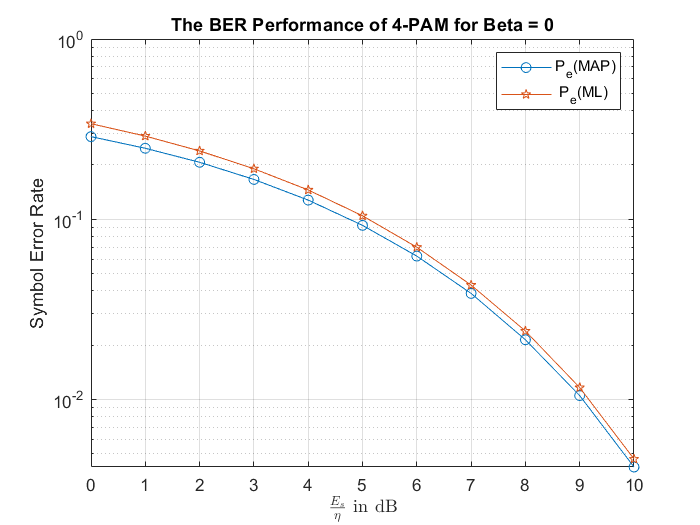

figure
semilogy(SNR_dB,PE_MAP,'-o',SNR_dB ,PE_ML,'-p')
grid on
title("The BER Performance of 4-PAM for Beta = " + Beta)
legend('P_{e}(MAP)',' P_{e}(ML)')
ylabel('Symbol Error Rate')
xlabel('$\frac{E_{s}}{\eta}$ in dB', 'interpreter', 'Latex');

%Functions

function [t , pulse] = Raised_Cosine_Pulse(T,Fs,Beta)
%Here we create t due to the hint in the project description.
t = -6*T:T/Fs:6*T;
%we create a pulse array corresponding to the length of t.
pulse = zeros(1,length(t));
%In this loop we generate our raised-cosine and fill our pulse array.
for i = 1 : length(t)
    %Here we check if t=+-T/2Beta or not if so we use the sinc function.
   if ((t(1,i) == -T/(2*Beta)) || ( t(1,i) == T/(2*Beta) ) )
       pulse(1,i) = (pi/4)*sinc(1/(2*Beta));
   else 
       pulse(1,i) = (cos(pi*Beta*t(1,i)/T).*sinc(t(1,i)/T))./((1-(2*Beta.*t(1,i)./T).^2));
   end
end
end